# Intro to Near-Field SAR Radar Imaging using the Range Migration Algorithm - Josiah W. Smith

Add Necessary Folders

addpath(genpath("../"))

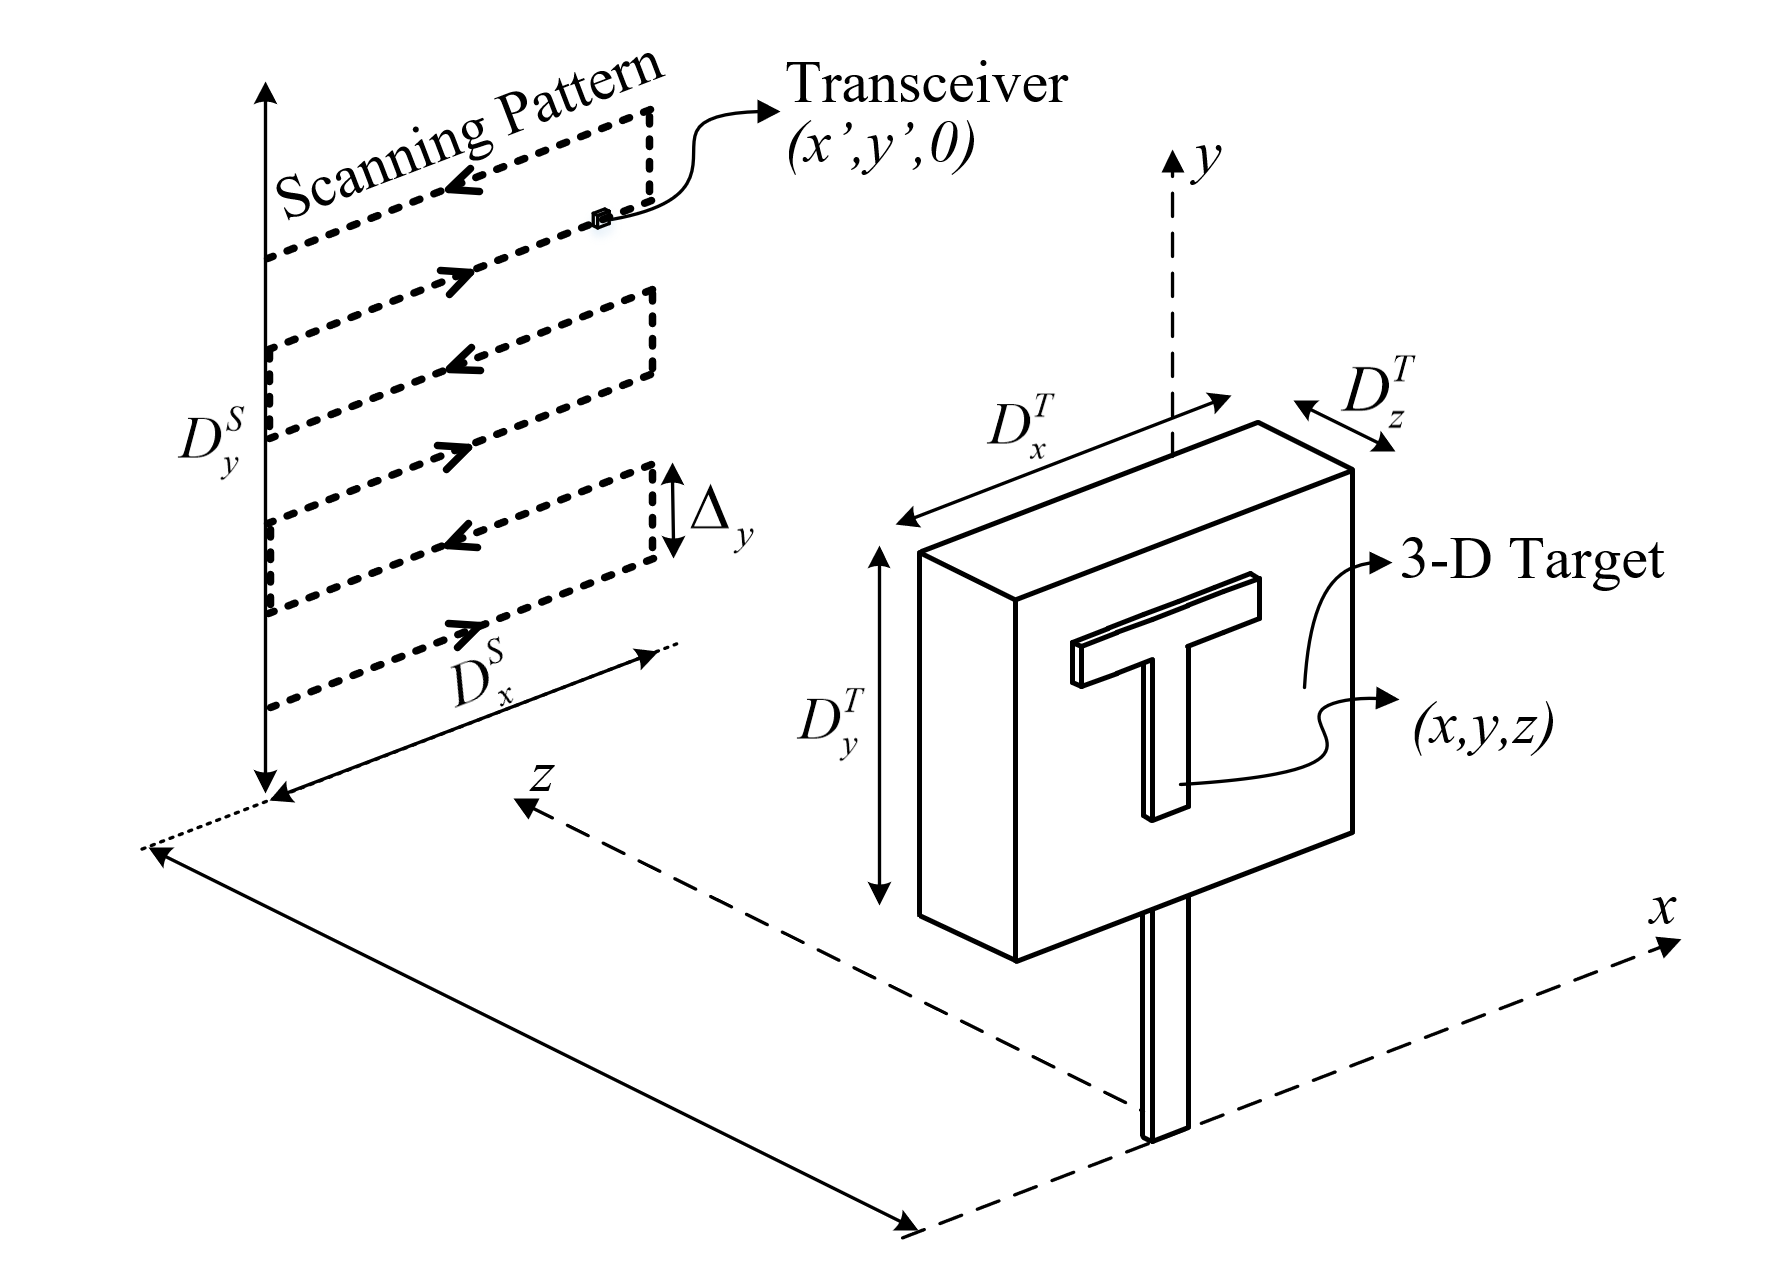

Monostatic transceivers at positions (x',y',0)

Target exists at points (x,y,z)

Radar beat signal is sampled along frequency. Thus, the return data has the form (x',y',k), where k is the frequency wavenumber domain.

## Set the FMCW Parameters

fmcw.c = physconst('lightspeed');           % Speed of light
fmcw.Nk = 64;                               % Number of time samples
fmcw.B = 4e9;                               % Bandwidth
fmcw.T = 100e-6;                            % Sample time
fmcw.fS = fmcw.Nk/fmcw.T;                   % Sample frequency
fmcw.K = fmcw.B/fmcw.T;                     % Chirp slope
fmcw.df = fmcw.K/fmcw.fS;                   % Frequency step
fmcw.f0 = 77e9;                             % Starting frequency
fmcw.fc = fmcw.f0 + fmcw.B/2;               % Center frequency
fmcw.lambda_m = fmcw.c/fmcw.fc;             % Center wavelength
fmcw.f = fmcw.f0 + (0:fmcw.Nk-1)*fmcw.df;   % Instantaneous frequency
fmcw.k = 2*pi/fmcw.c * fmcw.f;              % Instantaneous wavenumber


fmcw.Rmax = fmcw.fS*fmcw.c/(2*fmcw.K);      % Maximum Range
fmcw.Rres = fmcw.c/(2*4e9);                 % Range resolution

## Create SAR Array

sar.x_step_m = fmcw.lambda_m/4;
sar.Nx = 240;
sar.x_m = (-(sar.Nx-1)/2:(sar.Nx-1)/2) * sar.x_step_m;

sar.y_step_m = fmcw.lambda_m/4;
sar.Ny = 256;
sar.y_m = (-(sar.Ny-1)/2:(sar.Ny-1)/2) * sar.y_step_m;

sar.z_m = 0;
[sar.X,sar.Y,sar.Z] = ndgrid(sar.x_m,sar.y_m,sar.z_m);
sar.xyz_m = reshape(cat(3,sar.X,sar.Y,sar.Z),[],3);     % Array coordinates

## Create the Target

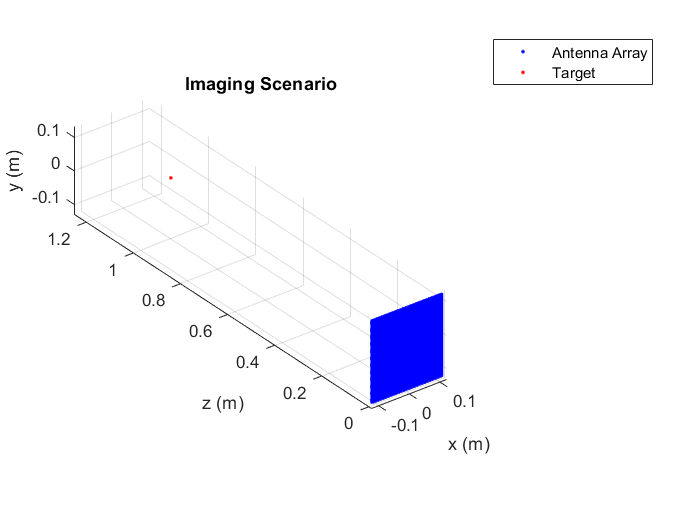

% Point Spread Function
target.xyz_m = [0,0.05,1];                  % Target coordinates
target.pxyz = ones(1,size(target.xyz_m,1)); % Target reflectivity

% 3x3x3 Grid
% [target.X,target.Y,target.Z] = ndgrid((-1:1)*0.1,(-1:1)*0.1,(-1:1)*0.1+1);
% target.xyz_m = reshape(cat(4,target.X,target.Y,target.Z),[],3);

target.Nt = size(target.xyz_m,1);           % Number of targets
showImagingScenario(target,sar)

## Simulate the Beat Signal

- Each transceiver at (x',y',0) response consists of a summation of the reflection from every reflector in the scene

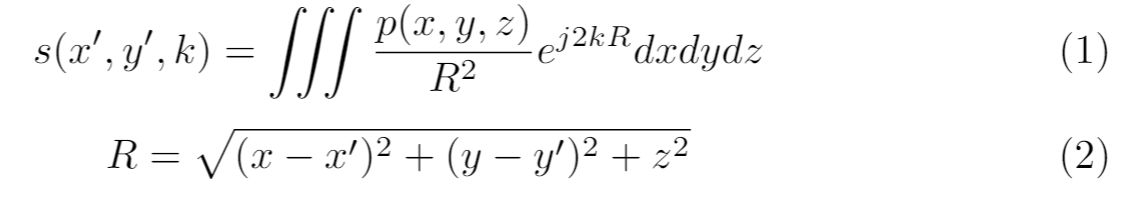

### First, compute R

sar.R_m = pdist2(single(sar.xyz_m),single(target.xyz_m));
% size: (Nx*Ny) x Nt

### Then, compute s(x',y',k)

sar.sarData = single(zeros(size(sar.xyz_m,1),length(fmcw.k)));
for indK = 1:fmcw.Nk
    sar.sarData(:,indK) = sum(sar.R_m.^(-2) .* exp(1j*2*fmcw.k(indK)*sar.R_m),2);
end
clear indK
sar.sarData = reshape(sar.sarData,sar.Nx,sar.Ny,fmcw.Nk);
% size: Nx x Ny x Nk

## How can we reconstruct the image? 

### First attempt: Back Projection Algorithm/Matched Filter (Effective, but too inefficient)

- Effective, but too computationally inefficient

- Simply invert the integral

- Has computational complexity of O(n^6), thus the six for loops below

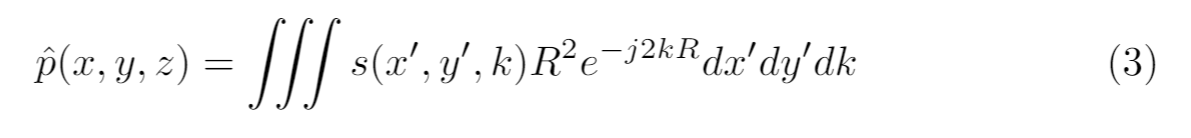

% Set coordinates over which to compute the matched filter
bpa.N = 256;
bpa.x_m = linspace(-0.2,0.2-0.4/bpa.N,bpa.N);
bpa.y_m = linspace(-0.2,0.2-0.4/bpa.N,bpa.N);
bpa.z_m = linspace(0.8,1.2-0.4/bpa.N,bpa.N);

bpa.pxyz = single(zeros(length(bpa.x_m),length(bpa.y_m),length(bpa.z_m)));

for indX = 1:length(bpa.x_m)
    for indY = 1:length(bpa.y_m)
        for indZ = 1:length(bpa.z_m)
            for indXp = 1:sar.Nx
                for indYp = 1:sar.Ny
                    for indK = 1:fmcw.Nk
                        bpa.R = sqrt((bpa.x_m(indX) - sar.x_m(indXp))^2 + (bpa.y_m(indY) - sar.y_m(indYp))^2 + bpa.z_m(indZ)^2);
                        bpa.bpaKernel = bpa.R.^2 .* exp(-1j*2*fmcw.k(indK)*bpa.R);
                        bpa.pxyz(indX,indY,indZ) = bpa.pxyz(indX,indY,indZ) + sar.sarData(indXp,indYp,indK) .* bpa.bpaKernel;
                    end
                end
            end
        end
    end
end

### Takes way too long that way - Try a more efficient implemention on the GPU

bpa.N = 128;
bpa.x_m = linspace(-0.2,0.2-0.4/bpa.N,bpa.N);
bpa.y_m = linspace(-0.2,0.2-0.4/bpa.N,bpa.N);
bpa.z_m = linspace(0.8,1.2-0.4/bpa.N,bpa.N);

bpa = SISO_BPA_2D_array_reconstructImage_3D(sar,fmcw,bpa);

## Look at Result

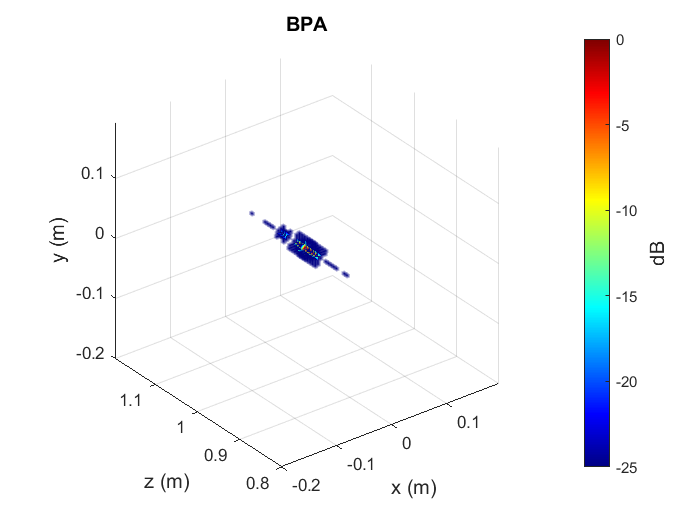

plotXYZdB(bpa.pxyz,bpa.x_m,bpa.y_m,bpa.z_m,[],-25,"BPA",12);

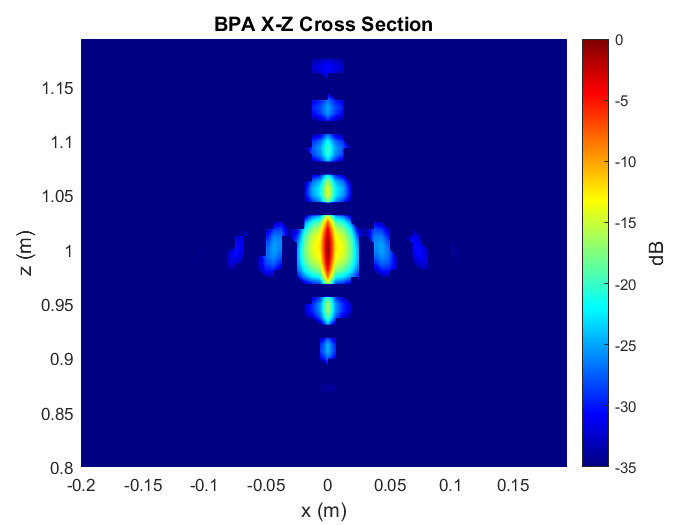

plotXYdB(squeeze(bpa.pxyz(:,end/2+1,:)),bpa.x_m,bpa.z_m,-35,"x (m)","z (m)","BPA X-Z Cross Section",12)

## A More Efficient Method

- The problem with (1) is the highly nonlinear phase term, spherical wavefront, dependent on R.

- Can we solve the problem with a simpler approach if we can approximate the phase term with something more linear?

- Yes, use the Method of Stationary Phase (MSP) to decompose the spherical wavefront in (1) into a superposition of plane waves. More info on MSP in attached PDF.

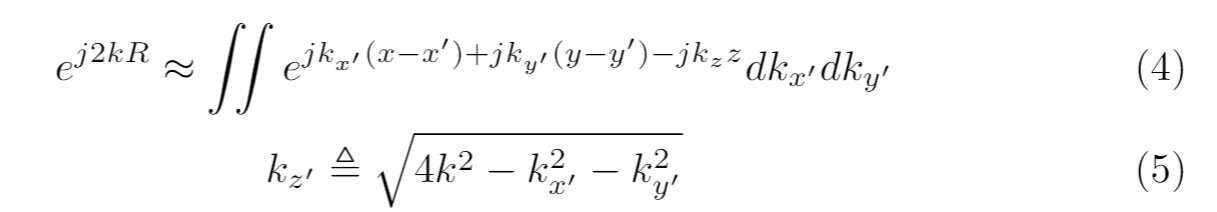

- Substitude (4) into (1) and ignore the amplitude term (1/R^2)

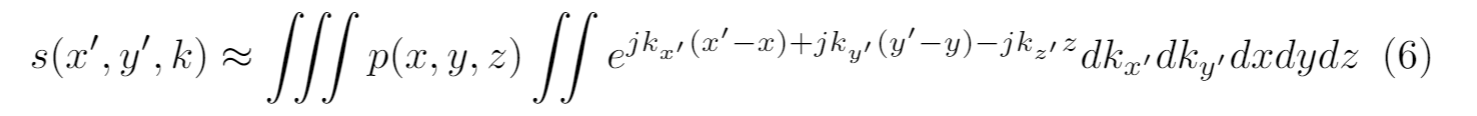

- Rearrange the inside of the integrals to form Fourier kernels

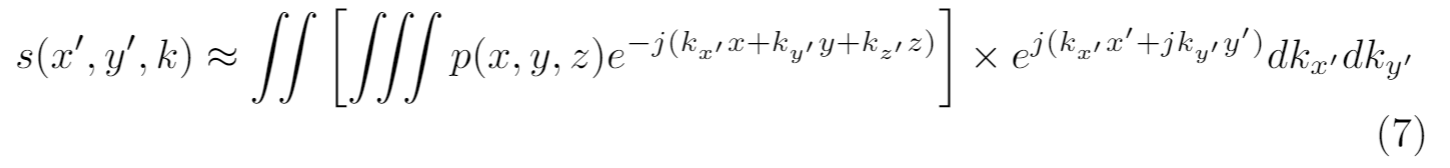

- Inside the square brackets is a 3-D Fourier transform with respect to x,y,z (remember that the (x',y') and (x,y) coordinate systems are coincident)

- The remaining terms outside the brackets are a 2-D inverse Fourier transform with respect to x' and y'. Therefore, do a forward Fourier transform on the other side of the equation with respect to x' and y'

- Need to perform interpolation to go from kx,ky,k to kx,ky,kz (the k variable is like the radial wavenumber, where kx is the horizonal wavenumber). This interpolation is called the Stolt operation

- Now, the image can be recovered from the spatial spectral (kx,ky,kz) domain to the spatial domain using a 3-D inverse Fourier transform 

- In summary, the algorithm has three steps. 1) take 2-D spatial Fourier transform over x' and y' of beat signal s(x',y',k). 2) perform Stolt interpolation to go from kx,ky,k to kx,ky,kz. 3) take 3-D inverse Fourier transform of resulting data

## Fourier-Based Method Implementation - Create Imaging Parameters

im.N = 64;
im.x_m = linspace(-0.2,0.2-0.4/im.N,im.N);
im.y_m = linspace(-0.2,0.2-0.4/im.N,im.N);
im.z_m = linspace(0.8,1.2-0.4/im.N,im.N);

im.nFFTx = 512;
im.nFFTy = 500;
im.nFFTz = 1024;

im = uniform_SISO_2D_array_reconstructImage_3D(sar,fmcw,im,true);

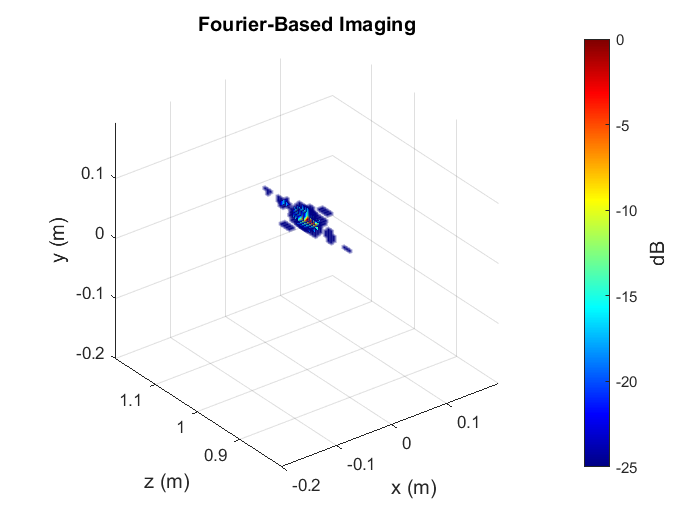

plotXYZdB(im.pxyz,im.x_m,im.y_m,im.z_m,[],-25,"Fourier-Based Imaging",12);

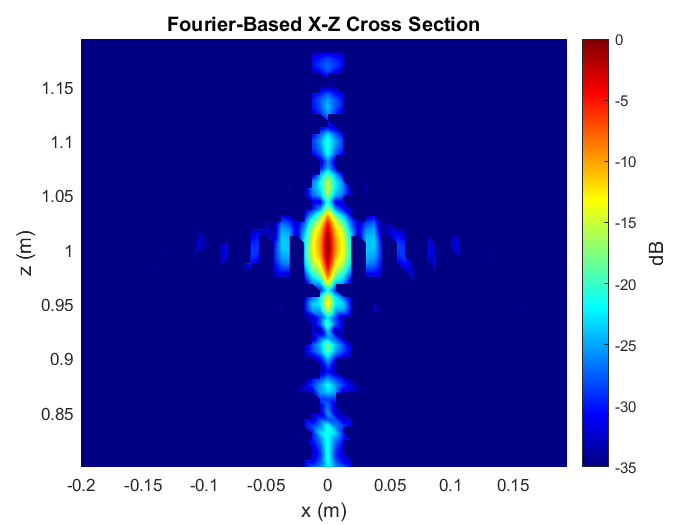

plotXYdB(squeeze(im.pxyz(:,end/2+1,:)),im.x_m,im.z_m,-35,"x (m)","z (m)","Fourier-Based X-Z Cross Section",12)